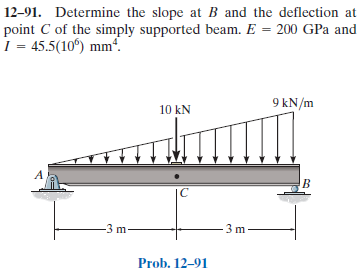

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-12-problem-91P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-12-problem-91P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

w1 = findpoly(1, 'thru', [0 0], [6*u.m -9*u.kN/u.m]);

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rb', 6*u.m);
b = b.add('concentrated', 'force', -10*u.kN, 3*u.m);
b = b.add('distributed', 'force', w1, [0 6]*u.m);
b.L = 6*u.m;

# section properties

b.E = rewrite(200*u.GPa, [u.kN u.m]);
b.I = rewrite(45.5e6*u.mm^4, u.m);

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('factor');
b.E = rewrite(b.E, u.GPa);
b.I = rewrite(b.I, u.mm);

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{x\,\left(3\,x^{4}-560\,x^{2}\,m^{2}+14472\,m^{4}\right)}{2184000}\,\frac{1}{m^{4}} & \text{ if }x\leq 3\,m\\ -\frac{\left(x-6\,m\right)\,\left(3\,x^{4}+18\,x^{3}\,m-52\,x^{2}\,m^{2}-3912\,x\,m^{3}+1800\,m^{4}\right)}{2184000}\,\frac{1}{m^{4}} & \text{ if }3\,m<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{5\,x^{4}-560\,x^{2}\,m^{2}+4824\,m^{4}}{728000}\,\frac{1}{m^{4}} & \text{ if }x\leq 3\,m\\ \frac{-5\,x^{4}+160\,x^{2}\,m^{2}+2400\,x\,m^{3}-8424\,m^{4}}{728000}\,\frac{1}{m^{4}} & \text{ if }3\,m<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} \frac{x\,\left(56\,m^{2}-x^{2}\right)}{4}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }x\leq 3\,m\\ -\frac{\left(x-6\,m\right)\,\left(x^{2}+6\,x\,m+20\,m^{2}\right)}{4}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }3\,m<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} \frac{56\,m^{2}-3\,x^{2}}{4}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }x\leq 3\,m\\ \frac{16\,m^{2}-3\,x^{2}}{4}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }3\,m<x \end{array}\right.$$

w

$$w(x) = -\frac{3\,x}{2}\,\frac{\mathrm{kN}}{m^{2}}$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} \mathrm{Ra} & 14\,\mathrm{kN}\\ \mathrm{Rb} & 23\,\mathrm{kN} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

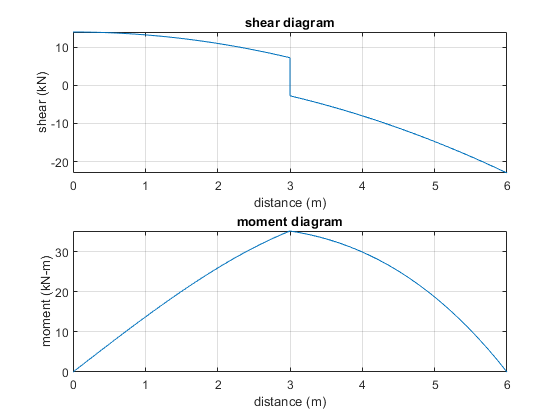

beam.shear_moment(m, v, [0 b.L], {'kN' 'm'});

# slope at B

dyB = dy(b.L)*u.rad;
dyB_vpa = vpa(dyB, 4) %#ok<NASGU> 

$$dyB\_vpa = 0.00722\,\mathrm{rad}$$

# deflection at C

yC = rewrite(y(b.L/2), u.mm);
yC_vpa = vpa(yC, 4) %#ok<NASGU> 

$$yC\_vpa = -13.29\,\mathrm{mm}$$

# clean up

addvar(y);
setassum(old_assum, 'clear');
clear dyB_vpa yC_vpa;
clear old_assum;